# Lab 1

clear; close; clc;

%bring in functions from ae 445
addpath(genpath('AE 445'));

## Get Data

% Airfoil Geometry
airfoil = loadAirfoil();
[DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c] = possitionDeltas(airfoil)

DxLower_c =          0    0.0112    0.0183    0.0248    0.0310    0.0373    0.0454    0.0524    0.0566    0.0603    0.0630    0.0646    0.0652    0.0646    0.0629    0.0602    0.0564    0.0516    0.0460    0.0396    0.0325    0.0249    0.0168    0.0085


DxUpper_c =          0    0.0085    0.0169    0.0251    0.0327    0.0398    0.0463    0.0519    0.0567    0.0604    0.0632    0.0648    0.0654    0.0648    0.0631    0.0603    0.0565    0.0512    0.0469    0.0421    0.0343    0.0252    0.0155    0.0058


DyLower_c =          0   -0.0082   -0.0060   -0.0047   -0.0043   -0.0044   -0.0046   -0.0041   -0.0027   -0.0011    0.0003    0.0016    0.0027    0.0035    0.0041    0.0045    0.0047    0.0047    0.0046    0.0042    0.0036    0.0029    0.0020    0.0010


DyUpper_c =          0    0.0014    0.0028    0.0040    0.0051    0.0059    0.0066    0.0070    0.0072    0.0072    0.0069    0.0064    0.0056    0.0045    0.0031    0.0016   -0.0002   -0.0022   -0.0052   -0.0088   -0.0120   -0.0139   -0.0141   -0.0130


xLower_c =     0.0037    0.0149    0.0332    0.0580    0.0890    0.1263    0.1717    0.2241    0.2806    0.3409    0.4039    0.4686    0.5337    0.5983    0.6613    0.7214    0.7778    0.8295    0.8755    0.9151    0.9476    0.9725    0.9894    0.9979


xUpper_c =     0.9979    0.9893    0.9724    0.9473    0.9146    0.8747    0.8285    0.7766    0.7199    0.6595    0.5963    0.5315    0.4662    0.4014    0.3383    0.2780    0.2215    0.1703    0.1235    0.0813    0.0470    0.0219    0.0064    0.0006


yLower_c =    -0.0048   -0.0130   -0.0190   -0.0237   -0.0280   -0.0324   -0.0370   -0.0411   -0.0438   -0.0449   -0.0445   -0.0429   -0.0402   -0.0367   -0.0326   -0.0280   -0.0233   -0.0185   -0.0140   -0.0098   -0.0062   -0.0033   -0.0013   -0.0003


yUpper_c =     0.0004    0.0018    0.0045    0.0085    0.0136    0.0195    0.0261    0.0331    0.0404    0.0476    0.0545    0.0609    0.0664    0.0709    0.0740    0.0756    0.0754    0.0732    0.0680    0.0592    0.0471    0.0332    0.0191    0.0061



% Experimental Data
opts = detectImportOptions("Lab1_Data.xlsx");
dataMatrix = readmatrix("Lab1_Data.xlsx", "Range", "A1:G51"); % Data in A2 trhough G51
% first row is angle of attack second row is static head thid row is total
% head subsiquent rows are local head measuremnts
AoAs = dataMatrix(1,:);
staticHeads = dataMatrix(2,:);
totalHeads = dataMatrix(3,:);
localHeads = dataMatrix(4:end,:); % I belice all is well with data imports

% initialize constants
rhoAir = 1.225; % kg/m^3
rhoLiquid = 826; % kg/m^3
c = .195; % m


%variabel for data to be saved in
countOfAoAs = length(AoAs);
countOPoints = length(localHeads);
Res = zeros(0, countOfAoAs);
Cls = zeros(0, countOfAoAs);
Cds = zeros(0, countOfAoAs);
Cmc_4s = zeros(0, countOfAoAs);
CpUppers  = zeros(countOPoints / 2, countOfAoAs);
CpLowers  = zeros(countOPoints / 2, countOfAoAs);


%TODO: repeat for each AOA
i=1 % make i for loop itteration var

i = 1

for i = 1:countOfAoAs
    
    alpha = AoAs(i)
    hs = staticHeads(i);
    ht = totalHeads(i);
    hlocal = localHeads(:,i);
    %[CpUpper, CpLower] = getCps(hs, ht, hlocal)
    [CpUppers(:,i), CpLowers(:,i)] = getCps(hs, ht, hlocal)
    
    vInf = velocityInf(ht,hs)
    
    % clalculate Rn for an AoA
    %Re = reynoldsNumber(vInf)
    Res(i) = reynoldsNumber(vInf)
    
    % calculate at one AoA; local coeffs: cp cl cd cm,c/4
    %[Cl, Cd, CmC_4] = getCoeffs(alpha, CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c,xLower_c, xUpper_c, yLower_c, yUpper_c)
    % [Cls(i), Cds(i), Cmc_4s(i)] = getCoeffs(alpha, CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c,xLower_c, xUpper_c, yLower_c, yUpper_c)
    [Cls(i), Cds(i), Cmc_4s(i)] = getCoeffs(alpha, CpUppers(i), CpLowers(i), DxLower_c, DxUpper_c, DyLower_c, DyUpper_c,xLower_c, xUpper_c, yLower_c, yUpper_c)
    %TODO: I belive there to be an error in get coeefs becuase cl of 1 seems
    %too high
    
    % a bunch of other stuff
end

alpha = -8

CpUppers =     0.4630         0         0         0         0         0         0
    0.8148         0         0         0         0         0         0
    0.5556         0         0         0         0         0         0
    0.2778         0         0         0         0         0         0
    0.1759         0         0         0         0         0         0
    0.2130         0         0         0         0         0         0
    0.2685         0         0         0         0         0         0
   -0.0926         0         0         0         0         0         0
   -0.1389         0         0         0         0         0         0
   -0.1389         0         0         0         0         0         0


CpLowers =    -0.2963         0         0         0         0         0         0
   -0.3148         0         0         0         0         0         0
   -0.2963         0         0         0         0         0         0
    0.2593         0         0         0         0         0         0
    0.6296         0         0         0         0         0         0
    0.5926         0         0         0         0         0         0
    0.4722         0         0         0         0         0         0
   -0.5648         0         0         0         0         0         0
    0.8333         0         0         0         0         0         0
    0.1852         0         0         0         0         0         0


vInf = 37.7993

Res = 5.0726e+05

Cls = -0.7495

Cds = 0.1013

Cmc_4s = 8.8838

alpha = -4

CpUppers =     0.4630    0.4762         0         0         0         0         0
    0.8148    0.7905         0         0         0         0         0
    0.5556    0.4762         0         0         0         0         0
    0.2778    0.2857         0         0         0         0         0
    0.1759    0.0571         0         0         0         0         0
    0.2130   -0.4762         0         0         0         0         0
    0.2685    0.2857         0         0         0         0         0
   -0.0926   -0.2000         0         0         0         0         0
   -0.1389   -0.2190         0         0         0         0         0
   -0.1389   -0.2000         0         0         0         0         0


CpLowers =    -0.2963   -0.0476         0         0         0         0         0
   -0.3148   -0.0952         0         0         0         0         0
   -0.2963   -0.0952         0         0         0         0         0
    0.2593    0.2952         0         0         0         0         0
    0.6296    0.7333         0         0         0         0         0
    0.5926    0.5714         0         0         0         0         0
    0.4722    0.4762         0         0         0         0         0
   -0.5648   -0.2857         0         0         0         0         0
    0.8333    0.8857         0         0         0         0         0
    0.1852    0.1524         0         0         0         0         0


vInf = 37.2706

Res = 	1.0e+05 *

    5.0726    5.0017


Cls =    -0.7495   -1.1233


Cds =     0.1013    0.0724


Cmc_4s =     8.8838   13.2124


alpha = 0

CpUppers =     0.4630    0.4762    0.4571         0         0         0         0
    0.8148    0.7905    0.5238         0         0         0         0
    0.5556    0.4762    0.1619         0         0         0         0
    0.2778    0.2857    0.2857         0         0         0         0
    0.1759    0.0571   -0.2571         0         0         0         0
    0.2130   -0.4762    0.1905         0         0         0         0
    0.2685    0.2857    0.2762         0         0         0         0
   -0.0926   -0.2000   -0.4381         0         0         0         0
   -0.1389   -0.2190   -0.4190         0         0         0         0
   -0.1389   -0.2000   -0.3524         0         0         0         0


CpLowers =    -0.2963   -0.0476   -0.0286         0         0         0         0
   -0.3148   -0.0952   -0.0667         0         0         0         0
   -0.2963   -0.0952   -0.0667         0         0         0         0
    0.2593    0.2952    0.2857         0         0         0         0
    0.6296    0.7333    0.7143         0         0         0         0
    0.5926    0.5714    0.5714         0         0         0         0
    0.4722    0.4762    0.4762         0         0         0         0
   -0.5648   -0.2857   -0.2381         0         0         0         0
    0.8333    0.8857    0.8667         0         0         0         0
    0.1852    0.1524    0.1810         0         0         0         0


vInf = 37.2706

Res = 	1.0e+05 *

    5.0726    5.0017    5.0017


Cls =    -0.7495   -1.1233   -0.8486


Cds =     0.1013    0.0724   -0.0045


Cmc_4s =     8.8838   13.2124    9.9644


alpha = 4

CpUppers =     0.4630    0.4762    0.4571    0.5577         0         0         0
    0.8148    0.7905    0.5238    0.0962         0         0         0
    0.5556    0.4762    0.1619   -0.2500         0         0         0
    0.2778    0.2857    0.2857    0.2788         0         0         0
    0.1759    0.0571   -0.2571   -0.6346         0         0         0
    0.2130   -0.4762    0.1905    0.1923         0         0         0
    0.2685    0.2857    0.2762    0.2885         0         0         0
   -0.0926   -0.2000   -0.4381   -0.7692         0         0         0
   -0.1389   -0.2190   -0.4190   -0.6250         0         0         0
   -0.1389   -0.2000   -0.3524   -0.5288         0         0         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096         0         0         0
   -0.3148   -0.0952   -0.0667   -0.0673         0         0         0
   -0.2963   -0.0952   -0.0667   -0.0769         0         0         0
    0.2593    0.2952    0.2857    0.3077         0         0         0
    0.6296    0.7333    0.7143    0.7212         0         0         0
    0.5926    0.5714    0.5714    0.5865         0         0         0
    0.4722    0.4762    0.4762    0.4808         0         0         0
   -0.5648   -0.2857   -0.2381   -0.1923         0         0         0
    0.8333    0.8857    0.8667    0.8654         0         0         0
    0.1852    0.1524    0.1810    0.2115         0         0         0


vInf = 37.0927

Res = 	1.0e+05 *

    5.0726    5.0017    5.0017    4.9778


Cls =    -0.7495   -1.1233   -0.8486   -0.0192


Cds =     0.1013    0.0724   -0.0045   -0.0018


Cmc_4s =     8.8838   13.2124    9.9644    0.2101


alpha = 8

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571         0         0
    0.8148    0.7905    0.5238    0.0962   -0.7143         0         0
    0.5556    0.4762    0.1619   -0.2500   -0.9524         0         0
    0.2778    0.2857    0.2857    0.2788   -0.0952         0         0
    0.1759    0.0571   -0.2571   -0.6346   -1.2095         0         0
    0.2130   -0.4762    0.1905    0.1923    0.1905         0         0
    0.2685    0.2857    0.2762    0.2885    0.2952         0         0
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476         0         0
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429         0         0
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095         0         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476         0         0
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476         0         0
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0         0
    0.2593    0.2952    0.2857    0.3077    0.2952         0         0
    0.6296    0.7333    0.7143    0.7212    0.7333         0         0
    0.5926    0.5714    0.5714    0.5865    0.5714         0         0
    0.4722    0.4762    0.4762    0.4808    0.4762         0         0
   -0.5648   -0.2857   -0.2381   -0.1923   -0.0952         0         0
    0.8333    0.8857    0.8667    0.8654    0.8857         0         0
    0.1852    0.1524    0.1810    0.2115    0.2571         0         0


vInf = 37.2706

Res = 	1.0e+05 *

    5.0726    5.0017    5.0017    4.9778    5.0017


Cls =    -0.7495   -1.1233   -0.8486   -0.0192    0.4459


Cds =     0.1013    0.0724   -0.0045   -0.0018    0.0645


Cmc_4s =     8.8838   13.2124    9.9644    0.2101   -5.3199


alpha = 12

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571    0.4762         0
    0.8148    0.7905    0.5238    0.0962   -0.7143   -2.1143         0
    0.5556    0.4762    0.1619   -0.2500   -0.9524   -2.0476         0
    0.2778    0.2857    0.2857    0.2788   -0.0952    0.3333         0
    0.1759    0.0571   -0.2571   -0.6346   -1.2095   -2.0476         0
    0.2130   -0.4762    0.1905    0.1923    0.1905    0.2190         0
    0.2685    0.2857    0.2762    0.2885    0.2952    0.3143         0
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476   -1.6190         0
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429   -1.1905         0
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095   -1.0000         0


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476   -0.0095         0
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476   -0.0190         0
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0         0
    0.2593    0.2952    0.2857    0.3077    0.2952    0.3333         0
    0.6296    0.7333    0.7143    0.7212    0.7333    0.7619         0
    0.5926    0.5714    0.5714    0.5865    0.5714    0.6476         0
    0.4722    0.4762    0.4762    0.4808    0.4762    0.5048         0
   -0.5648   -0.2857   -0.2381   -0.1923   -0.0952         0         0
    0.8333    0.8857    0.8667    0.8654    0.8857    0.9048         0
    0.1852    0.1524    0.1810    0.2115    0.2571    0.2952         0


vInf = 37.2706

Res = 	1.0e+05 *

    5.0726    5.0017    5.0017    4.9778    5.0017    5.0017


Cls =    -0.7495   -1.1233   -0.8486   -0.0192    0.4459    0.3682


Cds =     0.1013    0.0724   -0.0045   -0.0018    0.0645    0.0798


Cmc_4s =     8.8838   13.2124    9.9644    0.2101   -5.3199   -4.4542


alpha = 16

CpUppers =     0.4630    0.4762    0.4571    0.5577    0.4571    0.4762    0.5278
    0.8148    0.7905    0.5238    0.0962   -0.7143   -2.1143   -3.5185
    0.5556    0.4762    0.1619   -0.2500   -0.9524   -2.0476   -3.0741
    0.2778    0.2857    0.2857    0.2788   -0.0952    0.3333    0.4074
    0.1759    0.0571   -0.2571   -0.6346   -1.2095   -2.0476   -2.8796
    0.2130   -0.4762    0.1905    0.1923    0.1905    0.2190    0.2778
    0.2685    0.2857    0.2762    0.2885    0.2952    0.3143    0.3704
   -0.0926   -0.2000   -0.4381   -0.7692   -1.0476   -1.6190   -1.8519
   -0.1389   -0.2190   -0.4190   -0.6250   -0.9429   -1.1905   -1.5741
   -0.1389   -0.2000   -0.3524   -0.5288   -0.8095   -1.0000   -1.2500


CpLowers =    -0.2963   -0.0476   -0.0286   -0.0096   -0.0476   -0.0095   -0.0648
   -0.3148   -0.0952   -0.0667   -0.0673   -0.0476   -0.0190   -0.0463
   -0.2963   -0.0952   -0.0667   -0.0769   -0.0381         0    0.0093
    0.2593    0.2952    0.2857    0.3077    0.2952    0.3333    0.3704
    0.6296    0.7333    0.7143    0.7212    0.7333    0.7619    0.7593
    0.5926    0.5714    0.5714    0.5865    0.5714    0.6476    0.6019
    0.4722    0.4762    0.4762    0.4808    0.4762    0.5048    0.5370
   -0.5648   -0.2857   -0.2381   -0.1923   -0.0952         0    0.0833
    0.8333    0.8857    0.8667    0.8654    0.8857    0.9048    0.9259
    0.1852    0.1524    0.1810    0.2115    0.2571    0.2952    0.3704


vInf = 37.7993

Res = 	1.0e+05 *

    5.0726    5.0017    5.0017    4.9778    5.0017    5.0017    5.0726


Cls =    -0.7495   -1.1233   -0.8486   -0.0192    0.4459    0.3682    0.1937


Cds =     0.1013    0.0724   -0.0045   -0.0018    0.0645    0.0798    0.0562


Cmc_4s =     8.8838   13.2124    9.9644    0.2101   -5.3199   -4.4542   -2.3947


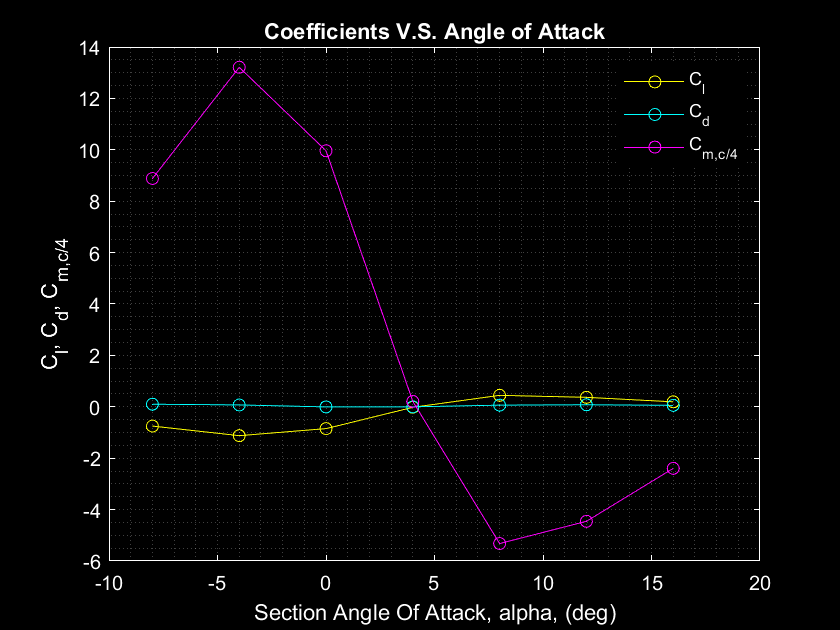



% Make charts for forty-eight distributions of pressure coefficients corresponding to all AoA s. 
% Indicate the Reynolds number of each AoA. 
% Having graphical illustrations would be better, but not mandatory.

figure;
plotScalarVsAoA([AoAs; Cls; Cds; Cmc_4s])

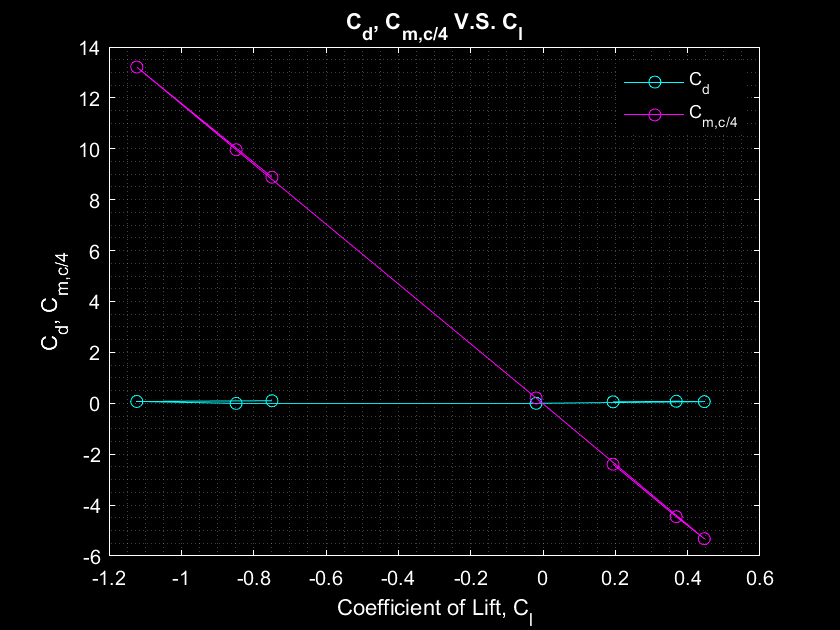

figure;
plotScalarVsCl(Cls, Cds, Cmc_4s)

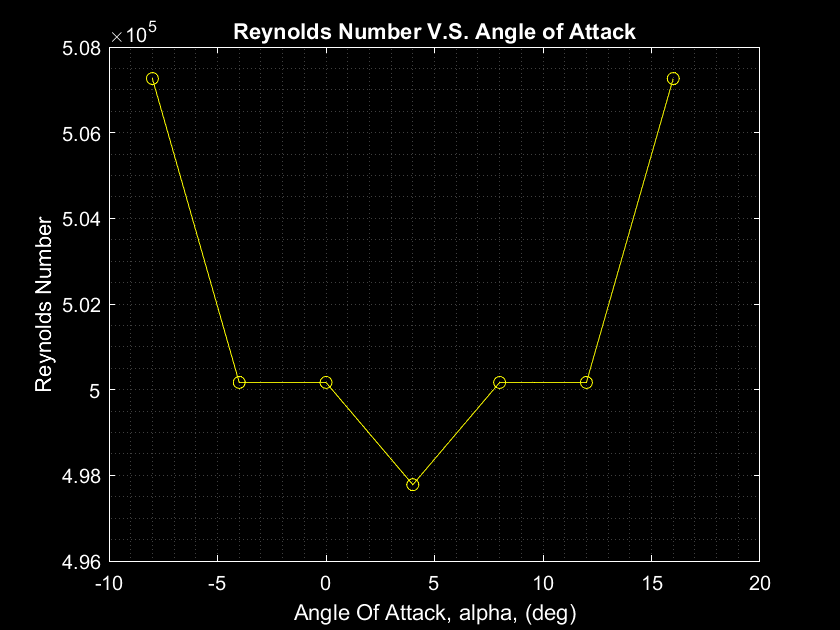

figure;
plotReVsAoa(Res,AoAs)

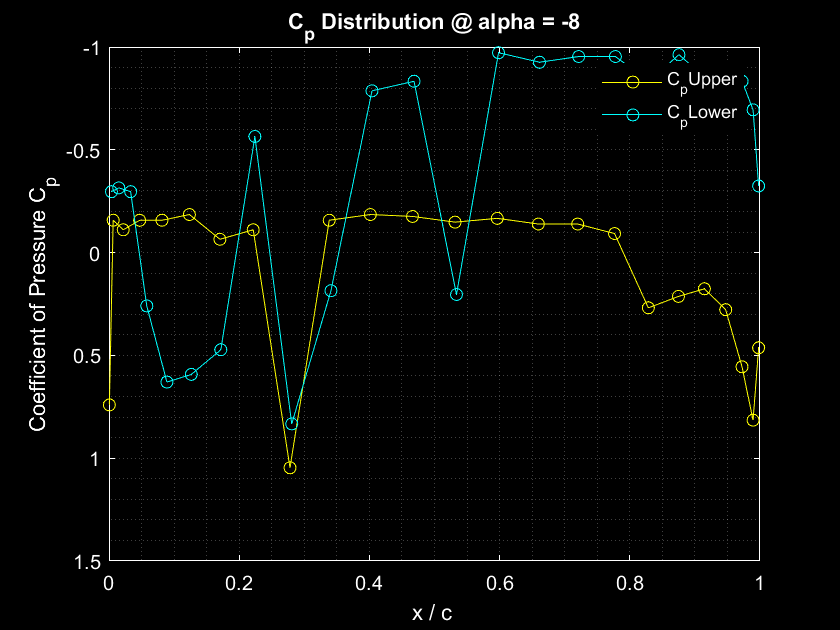

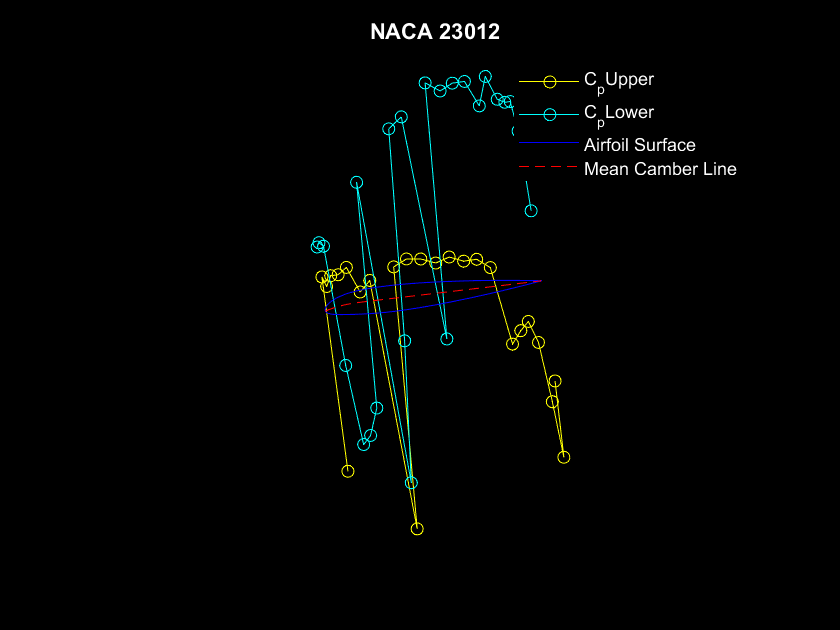

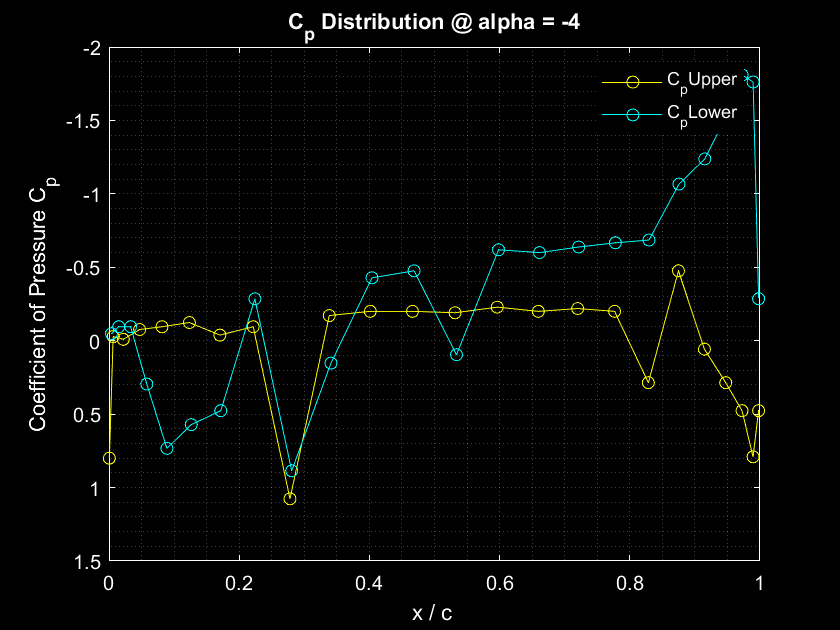

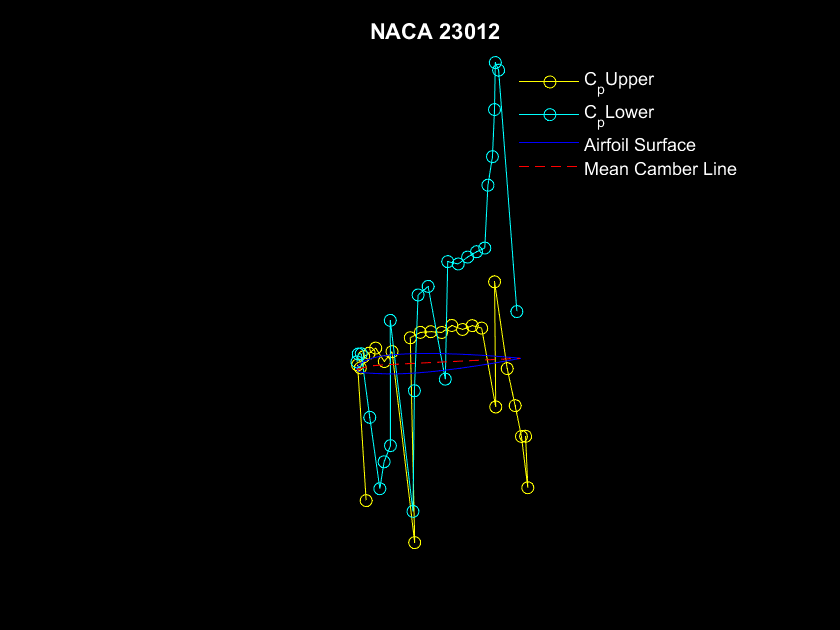

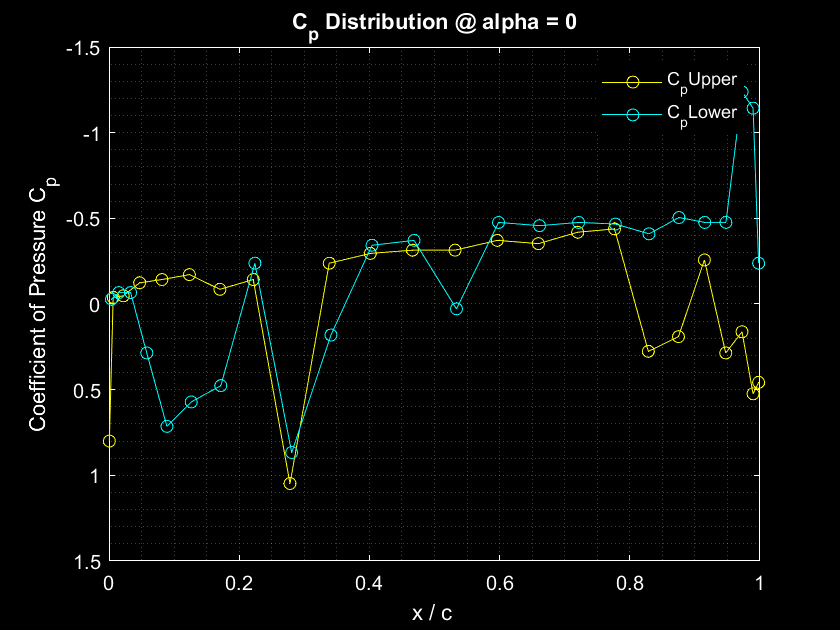

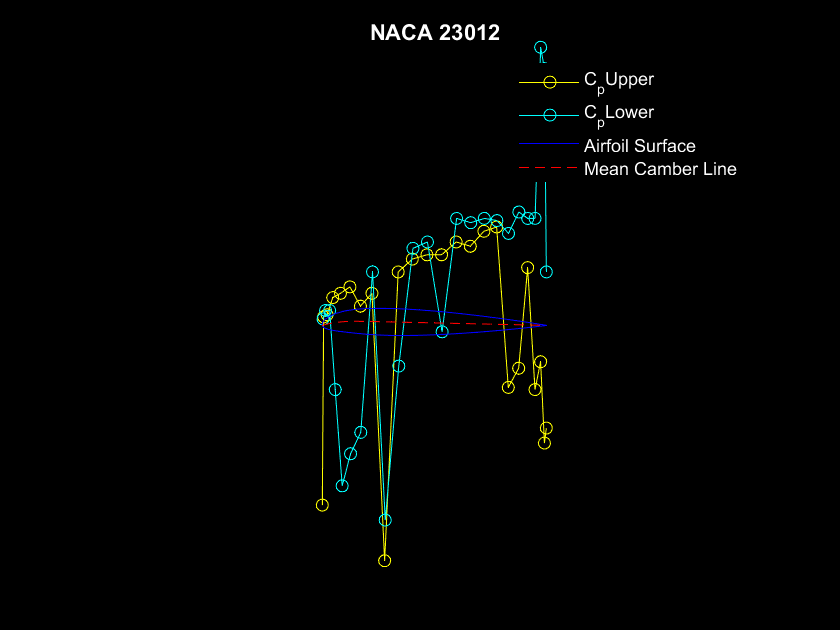

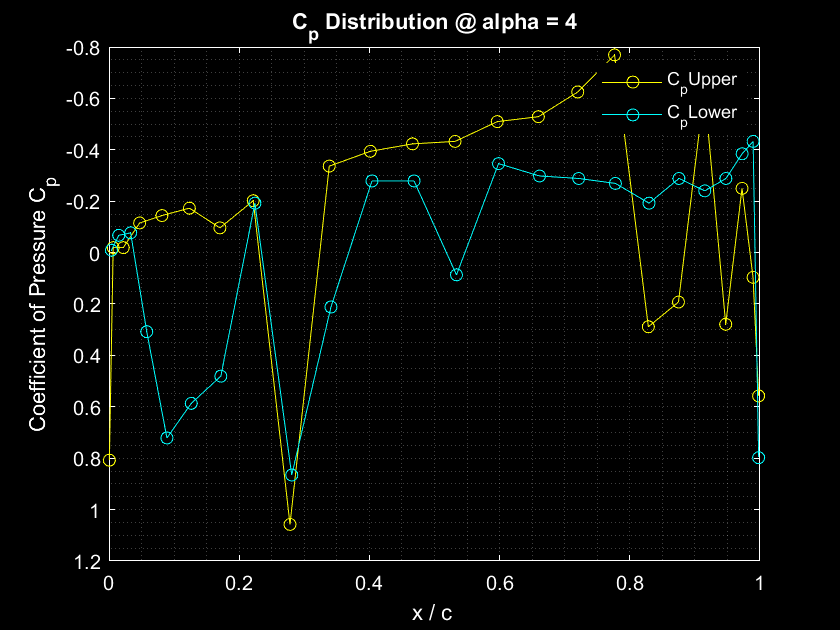

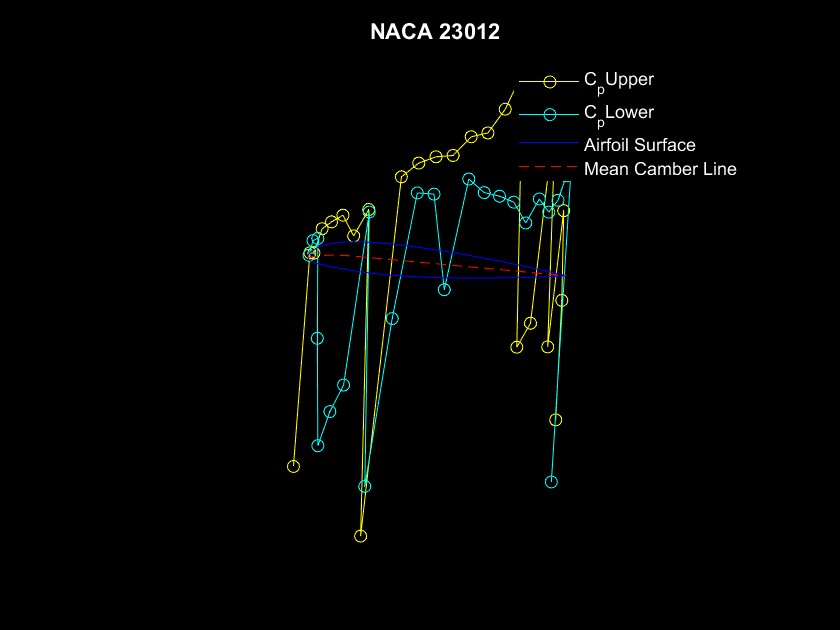


%probably put this inside the loop
for i = 1:countOfAoAs
    figure;
    %dont forget to put Re in these plots
    plotCpDistribution(airfoil,CpUppers(:,i),CpLowers(:,i),AoAs(i))
    figure;
    plotCpDistributionWithAirfoil(airfoil,CpUppers(:,i),CpLowers(:,i),AoAs(i))
end


%Make figures for total coefficients of lift, drag and moment on the quarter chord corresponding to different AoA s, just like Fig.1&2.
% These results should be compared  with theoretical results, which can either be calculated by the classical thin airfoil theory or extracted from Fig.1 & 2


function Re = reynoldsNumber(v)
    mu = 1.78E-5; % kg/(m*s)
    rho = 1.225; % kg/m^3
    c = .195; % m
    Re = rho * v * c / mu;
end

function vInf = velocityInf(ht,hs)
    rhoAir = 1.225; % kg/m^3
    rhoLiquid = 826; % kg/m^3
    g = 9.81; % m/s^2
    vInf = sqrt(2 * rhoLiquid * g * abs(ht-hs) / rhoAir); % m/s
end

function airfoil = loadAirfoil()
    iaf.designation='23012';
    iaf.n=24;
    iaf.HalfCosineSpacing=1;
    iaf.wantFile=1;
    iaf.datFilePath='./'; % Current folder
    iaf.is_finiteTE=0;
    airfoil = naca5gen(iaf);
end

function [DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c] = possitionDeltas(airfoil)
    % I belive this need updating and position os sensors is average of the
    % beteen points given
    xL = airfoil.xL;
    xU = airfoil.xU;
    yL = airfoil.zL;
    yU = airfoil.zU;
    %careful with bounds runfrom begining+1 to end-1
    DxLower_c = zeros(length(xL),0);
    DxUpper_c = zeros(length(xL),0);
    DyLower_c = zeros(length(xL),0);
    DyUpper_c = zeros(length(xL),0);
    
    xLower_c = zeros(length(xL),0);
    xUpper_c = zeros(length(xL),0);
    yLower_c = zeros(length(xL),0);
    yUpper_c = zeros(length(xL),0);
    
    for i = 2:length(xL)-1
        DxLower_c(i) = abs(1/2 * (xL(i+1) - xL(i-1)));
        DxUpper_c(i) = abs(1/2 * (xU(i+1) - xU(i-1)));
        DyLower_c(i) = 1/2 * (yL(i+1) - yL(i-1));
        DyUpper_c(i) = 1/2 * (yU(i+1) - yU(i-1));
        
%         xLower_c(i) = xL(i); %TODO: should this be + the average?
%         xUpper_c(i) = xU(i);
%         yLower_c(i) = yL(i);
%         yUpper_c(i) = yU(i);
    end
        %testing this out
        xLower_c = ((xL(1:end-1) + xL(2:end)) / 2)'; %TODO: should this be + the average?
        xUpper_c = ((xU(1:end-1) + xU(2:end)) / 2)'; 
        yLower_c = ((yL(1:end-1) + yL(2:end)) / 2)'; 
        yUpper_c = ((yU(1:end-1) + yU(2:end)) / 2)'; 
        
        %just a guess
        %DxLower_c = (xLower_c - xL(1:end-1)') * 2;
    
    
end

function cp = getCp(hs, ht, h)
    cp = (h-hs)./(ht-hs);
end

function [CpUpper, CpLower] = getCps(hs, ht, hlocal)
    hUpper = hlocal(1:end/2);
    hLower = hlocal(end/2+1:end);
    CpUpper = getCp(hs, ht, hUpper);
    CpLower = getCp(hs, ht, hLower);
end


function [Cn, Ca, CmLe] = coefficientsOfForce(CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c)
    Cn = sum(CpLower) * sum(DxLower_c) - sum(CpUpper) * sum(DxUpper_c) ;
    Ca = sum(CpLower) * sum(DyLower_c) - sum(CpUpper) * sum(DyUpper_c);
    CmLe = sum(CpUpper) * sum(DxUpper_c) * sum(xUpper_c) - sum(CpLower) * sum(DxLower_c) * sum(xLower_c) + sum(CpUpper) * sum(DyUpper_c) * sum(yUpper_c) - sum(CpLower) * sum(DyLower_c) * sum(yLower_c);
end

function [Cl, Cd, CmC_4] = coefficientsOfAerodynamicForces(alpha, CoefForce)
    Cn = CoefForce(1);
    Ca = CoefForce(2);
    CmLe = CoefForce(3);
    Cl = Cn * cosd(alpha) - Ca * sind(alpha);
    Cd = Cn * sind(alpha) + Ca * cosd(alpha);
    CmC_4 = CmLe + Cl / 4;
end

function [Cl, Cd, CmC_4] = getCoeffs(alpha, CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c)
    [Cn, Ca, CmLe] = coefficientsOfForce(CpUpper, CpLower, DxLower_c, DxUpper_c, DyLower_c, DyUpper_c, xLower_c, xUpper_c, yLower_c, yUpper_c);
    CoefForce = [Cn, Ca, CmLe];
    [Cl, Cd, CmC_4] = coefficientsOfAerodynamicForces(alpha, CoefForce);
end

function plotAirfoil(airfoil,alpha)
    % TODO: consider implementing alpha later
    % for alpha we want to move airfoil to center of rotation, rotate and
    % then translate it back
    % TODO: mayby implement alpha by passing a transformation matrix
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    name = airfoil.name;
    
    hold on;
    airfoilPlot(1) = plot(x,z,'b-');
    set(airfoilPlot(1),'DisplayName','Airfoil Surface');
%     plot(xU,zU,'bo-')
%     plot(xL,zL,'ro-')

    airfoilPlot(2) = plot(xC,zC,'r--');
    set(airfoilPlot(2),'DisplayName','Mean Camber Line');

    title(name)
end

function plotCpDistribution(airfoil,CpUpper,CpLower,alpha)
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    
    %consider plotting lift at that cord value as well
    % calculate pressure sensor locations
    xUs = (xU(1:end-1) + xU(2:end)) / 2;
    xLs = (xL(1:end-1) + xL(2:end)) / 2;
    
    plot1(1) = plot(xUs,CpUpper,'yo-'); hold on;
    plot1(2) = plot(xLs,CpLower,'co-'); hold on;
    
    set(plot1(1),'DisplayName','C_pUpper','Color',[1 1 0]); set(plot1(2),'DisplayName','C_pLower','Color',[0 1 1]);
    set(gca,'YDir','reverse'); %reversed because it makes sense as up and down pressures
    
    title(sprintf("C_p Distribution @ alpha = %g", alpha),"Color",'w'); xlabel('x / c ','Color','w'); ylabel('Coefficient of Pressure C_p','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
    
end

function plotCpDistributionWithAirfoil(airfoil,CpUpper,CpLower,alpha)
    x = airfoil.x; z = airfoil.z;
    xU = airfoil.xU; zU = airfoil.zU;
    xL = airfoil.xL; zL = airfoil.zL;
    xC = airfoil.xC; zC = airfoil.zC;
    
    %consider plotting lift at that cord value as well
    % calculate pressure sensor locations
    xUs = (xU(1:end-1) + xU(2:end)) / 2;
    xLs = (xL(1:end-1) + xL(2:end)) / 2;
    
    zUs = (zU(1:end-1) + zU(2:end)) / 2;
    zLs = (zL(1:end-1) + zL(2:end)) / 2;
    
%     plot1(1) = plot(xUs,-CpUpper + zUs,'yo-'); hold on;
%     plot1(2) = plot(xLs,-CpLower + zUs,'co-'); hold on;
    plot1(1) = plot(xUs,-CpUpper,'yo-'); hold on;
    plot1(2) = plot(xLs,-CpLower,'co-'); hold on;
    
    set(plot1(1),'DisplayName','C_pUpper','Color',[1 1 0]); set(plot1(2),'DisplayName','C_pLower','Color',[0 1 1]);
    %set(gca,'YDir','reverse');
    
    title(sprintf("C_p Distribution With airfoil @ alpha = %g", alpha),"Color",'w'); xlabel('x / c ','Color','w'); ylabel('Coefficient of Pressure C_p','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
    
    hold on
    plotAirfoil(airfoil,alpha)
    axis equal
    
    camroll(-alpha)
    hold on
    axis off
    
end

function plotReVsAoa(Re,AoA)
    plot1 = plot(AoA,Re,'wo-'); hold on;
    title("Reynolds Number V.S. Angle of Attack","Color",'w'); xlabel('Angle Of Attack, alpha, (deg)','Color','w'); ylabel('Reynolds Number','Color','w');
    set(plot1,'DisplayName','Reynolds Number','Color',[1 1 0]);
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
end

function plotScalarVsAoA(scalars)
    AoA = scalars(1,:);
    %Re = scalars(2,:); %Re is aprox const
    Cl = scalars(2,:);
    Cd = scalars(3,:);
    Cmc_4 = scalars(4,:);
    
    plot1(1) = plot(AoA,Cl,'yo-'); hold on;
    plot1(2) = plot(AoA,Cd,'co-'); hold on;
    plot1(3) = plot(AoA,Cmc_4,'magentao-'); hold on;
    
    set(plot1(1),'DisplayName','C_l','Color',[1 1 0]); set(plot1(2),'DisplayName','C_d','Color',[0 1 1]); set(plot1(3),'DisplayName','C_m_,_c_/_4','Color',[1 0 1]);
    
    title("Coefficients V.S. Angle of Attack","Color",'w'); xlabel('Section Angle Of Attack, alpha, (deg)','Color','w'); ylabel('C_l, C_d, C_m_,_c_/_4','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
end

function plotScalarVsCl(Cl,Cd,Cmc_4)
    %Re = scalars(2,:); %Re is aprox const
%     Cl = scalars(1,:);
%     Cd = scalars(2,:);
%     Cmc_4 = scalars(3,:);
    
    plot1(1) = plot(Cl,Cd,'co-'); hold on;
    plot1(2) = plot(Cl,Cmc_4,'magentao-'); hold on;
    
    set(plot1(1),'DisplayName','C_d','Color',[0 1 1]); 
    set(plot1(2),'DisplayName','C_m_,_c_/_4','Color',[1 0 1]);
    
    title("C_d, C_m_,_c_/_4 V.S. C_l","Color",'w'); xlabel('Coefficient of Lift, C_l','Color','w'); ylabel('C_d, C_m_,_c_/_4','Color','w');
    
    set(gca, 'color','k', 'xcolor','w', 'ycolor','w'); set(gcf, 'color','k');
    grid(gca,"minor"); box(gca,'on'); hold(gca,'off');
    
    % Create legend
    legend1 = legend(gca,'show'); set(legend1,'TextColor',[1 1 1],'Orientation','vertical','Location','northeast','EdgeColor','none');
end